# Ejercicio Nº8

clear;clc;

syms t vc1(t) vc3(t) vc5(t) vc6(t) E;

## Valores de los componentes 

R1=1;
R2=1;
K1=1;
K2=2;
K3=3;
K4=4;
K5=5;
K6=6;

Se plantean las ecuaciones y se obtienen las matrices de la forma generalizada

M=[K1*R1 0 K5*R1 0;-R2*K2 0 (K5*R2+R2*K2) -R2*K2; K1 -K3 0 -K6;K2 -K4 -K2 K6+K4+K2];
N=[1 1 0 0;-1 -1 1 0;0 0 0 0;0 0 0 0];
u=[E;0;0;0];


Se expresan las matrices de la forma normalizada

A=-1.*(M\N);

B=M\u;

Se definen las variables de estado

x=[vc1;vc3;vc5;vc6];

Expresando el sistema en forma diferencial

odes = diff(x) ==  A*x + B;

Resolviendo el sistema con el comando dsolve

[vc1Sol(t), vc3Sol(t),vc5(t),vc6(t)] = dsolve(odes);
syms C1 C2 C3 C4
v01=0;
v02=0;
v03=0;
v04=0;
v05=0;
v06=0;
Xant=[v01;v03;v05;v06];
constantes=x(0)==Xant;
odes = diff(x) == A*x + B

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}{\mathrm{vc}}_{1}\left(t\right)=\frac{102\,\text{E}}{247}-\frac{177\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{177\,{\mathrm{vc}}_{3}\left(t\right)}{247}+\frac{75\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{3}\left(t\right)=\frac{35\,\text{E}}{247}-\frac{68\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{68\,{\mathrm{vc}}_{3}\left(t\right)}{247}+\frac{33\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{5}\left(t\right)=\frac{29\,\text{E}}{247}-\frac{14\,{\mathrm{vc}}_{1}\left(t\right)}{247}-\frac{14\,{\mathrm{vc}}_{3}\left(t\right)}{247}-\frac{15\,{\mathrm{vc}}_{5}\left(t\right)}{247}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{6}\left(t\right)=\frac{9\,{\mathrm{vc}}_{1}\left(t\right)}{494}-\frac{\text{E}}{494}+\frac{9\,{\mathrm{vc}}_{3}\left(t\right)}{494}-\frac{4\,{\mathrm{vc}}_{5}\left(t\right)}{247} \end{array}\right)$$

[vc1Sol(t), vc3Sol(t),vc5Sol(t),vc6Sol(t)] = dsolve(odes,constantes)

$$vc1Sol(t) = \begin{array}{l} {\mathrm{e}}^{-\sigma_{2}}\,\left(\sigma_{3}+\frac{243}{14}\right)\,\left(\frac{\text{E}\,{\mathrm{e}}^{\sigma_{2}}\,\left(67\,\sqrt{11713}+901\right)}{3604\,\left(\sqrt{11713}+130\right)}-\frac{57\,\sqrt{11713}\,\text{E}\,\left(\sqrt{11713}-137\right)}{3604\,\left(\sqrt{11713}-130\right)\,\left(\sqrt{11713}+130\right)}\right)-{\mathrm{e}}^{\sigma_{1}}\,\left(\sigma_{3}-\frac{243}{14}\right)\,\left(\frac{\text{E}\,{\mathrm{e}}^{-\sigma_{1}}\,\left(67\,\sqrt{11713}-901\right)}{3604\,\left(\sqrt{11713}-130\right)}-\frac{2793\,\text{E}\,\left(101\,\sqrt{11713}+11713\right)}{901\,\left(\sqrt{11713}+59\right)\,\left(\sqrt{11713}-130\right)\,\left(\sqrt{11713}+130\right)}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\left(\sqrt{11713}-130\right)}{247}\\ \sigma_{2}=\frac{t\,\left(\sqrt{11713}+130\right)}{247}\\ \sigma_{3}=\frac{3\,\sqrt{11713}}{14} \end{array}$$

$$vc3Sol(t) = \begin{array}{l} {\mathrm{e}}^{-\sigma_{2}}\,\left(\frac{\sqrt{11713}}{14}+\frac{109}{14}\right)\,\left(\frac{\text{E}\,{\mathrm{e}}^{\sigma_{2}}\,\left(67\,\sqrt{11713}+901\right)}{3604\,\left(\sqrt{11713}+130\right)}-\frac{57\,\sqrt{11713}\,\text{E}\,\left(\sqrt{11713}-137\right)}{3604\,\left(\sqrt{11713}-130\right)\,\left(\sqrt{11713}+130\right)}\right)-{\mathrm{e}}^{\sigma_{1}}\,\left(\frac{\sqrt{11713}}{14}-\frac{109}{14}\right)\,\left(\frac{\text{E}\,{\mathrm{e}}^{-\sigma_{1}}\,\left(67\,\sqrt{11713}-901\right)}{3604\,\left(\sqrt{11713}-130\right)}-\frac{2793\,\text{E}\,\left(101\,\sqrt{11713}+11713\right)}{901\,\left(\sqrt{11713}+59\right)\,\left(\sqrt{11713}-130\right)\,\left(\sqrt{11713}+130\right)}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\left(\sqrt{11713}-130\right)}{247}\\ \sigma_{2}=\frac{t\,\left(\sqrt{11713}+130\right)}{247} \end{array}$$

$$vc5Sol(t) = \begin{array}{l} {\mathrm{e}}^{-\sigma_{2}}\,\left(\frac{\sqrt{11713}}{14}-\frac{59}{14}\right)\,\left(\frac{\text{E}\,{\mathrm{e}}^{\sigma_{2}}\,\left(67\,\sqrt{11713}+901\right)}{3604\,\left(\sqrt{11713}+130\right)}-\frac{57\,\sqrt{11713}\,\text{E}\,\left(\sqrt{11713}-137\right)}{3604\,\left(\sqrt{11713}-130\right)\,\left(\sqrt{11713}+130\right)}\right)-{\mathrm{e}}^{\sigma_{1}}\,\left(\frac{\sqrt{11713}}{14}+\frac{59}{14}\right)\,\left(\frac{\text{E}\,{\mathrm{e}}^{-\sigma_{1}}\,\left(67\,\sqrt{11713}-901\right)}{3604\,\left(\sqrt{11713}-130\right)}-\frac{2793\,\text{E}\,\left(101\,\sqrt{11713}+11713\right)}{901\,\left(\sqrt{11713}+59\right)\,\left(\sqrt{11713}-130\right)\,\left(\sqrt{11713}+130\right)}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\left(\sqrt{11713}-130\right)}{247}\\ \sigma_{2}=\frac{t\,\left(\sqrt{11713}+130\right)}{247} \end{array}$$

$$vc6Sol(t) = \begin{array}{l} -{\mathrm{e}}^{-\sigma_{2}}\,\left(\frac{\text{E}\,{\mathrm{e}}^{\sigma_{2}}\,\left(67\,\sqrt{11713}+901\right)}{3604\,\left(\sqrt{11713}+130\right)}-\frac{57\,\sqrt{11713}\,\text{E}\,\left(\sqrt{11713}-137\right)}{3604\,\left(\sqrt{11713}-130\right)\,\left(\sqrt{11713}+130\right)}\right)-{\mathrm{e}}^{\sigma_{1}}\,\left(\frac{\text{E}\,{\mathrm{e}}^{-\sigma_{1}}\,\left(67\,\sqrt{11713}-901\right)}{3604\,\left(\sqrt{11713}-130\right)}-\frac{2793\,\text{E}\,\left(101\,\sqrt{11713}+11713\right)}{901\,\left(\sqrt{11713}+59\right)\,\left(\sqrt{11713}-130\right)\,\left(\sqrt{11713}+130\right)}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\left(\sqrt{11713}-130\right)}{247}\\ \sigma_{2}=\frac{t\,\left(\sqrt{11713}+130\right)}{247} \end{array}$$

clear  t
solu=[];
ti=0;
tf=10;
h=0.1;
for t=ti:h:tf
    if t<=5
    E=(sin(0.2*pi*t))^2;
    else
     E=0;
    end
    u=[E;0;0;0];
     X=((((1/h).*M)+N)\u) + ((((1/h).*M)+N)\((1/h).*M)*Xant);
    solu=[solu X];
    Xant=X;
end

## Gráfico

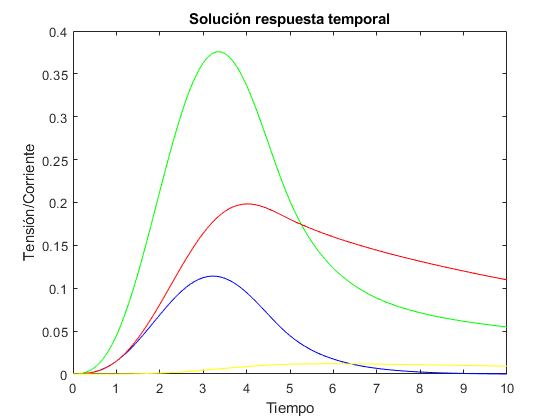

solu=solu';
t=ti:h:tf;
plot(t,solu(:,1),'g',t,solu(:,2),'b',t,solu(:,3),'-r',t,solu(:,4),'y');
title('Solución respuesta temporal');
xlabel('Tiempo');
ylabel('Tensión/Corriente');